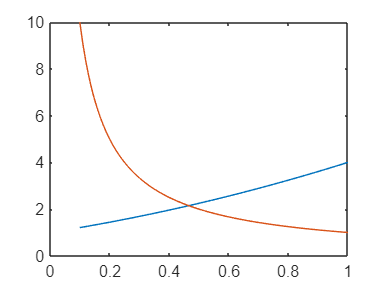

format long
eps=0.001;
F = @(x) (x+1).^2-1./x;

F1 = @(x) (x+1).^2;

F2 = @(x) 1./x;

x=[0.1:0.01:1];
plot(x, F1(x))%построение графика
hold on 
plot(x, F2(x))

a=0.4;
b=0.6;
a1=a;
a2=a;
b1=b;
b2=b;
%метод простых итераций
x0=(a+b)/2;%ищем середину
ii=0;
ii_max=100;
while 1

kor3 = x0;
ii=ii+1;
%df = (F(kor3+eps)-F(kor3-eps))/eps;
%g = -1/(df+1);
g=1./(kor3+1).^2;

x0 = g;
if ii>ii_max
   
break;
%elseif abs(F(kor3)) <=eps
%break;

elseif abs(x0-kor3)<=eps
    kor3=x0;
    break;
%объяснить почему эта функция

end

end
kor3; % корень
ii; % кол-во итераций

%Метод половинного деления
while(abs(b1-a1)>eps)%сокращаем область нахождения решения, пока не будет достигнута заданная точность
x0=(a1+b1)/2;%середина отрезка
if(F(x0)*F(a1)<0)%проверяем уловие 
b1=x0;%выбираем отрезок который содержит корень
else
a1=x0;
end
end

kor1=(a1+b1)/2;
%метод ньютона

[d1,d2]=Derivative(sym(F));
if (F(a)*d2(a)) > 0
x0 = a;%выбор начальной точки
else
x0 = b;
end

kor2=x0;
xi = b;
while abs(kor2-xi)>eps
xi = kor2;
kor2 = xi - (F(xi) / d1(xi));%формулы из леции
end
syms w;
vpasolve((w+1).^2==1./w,w,[0.4 0.6])

$$ans = 0.46557123187676802665673122521994$$

kor1%половинное деление

kor1 =    0.465234375000000


kor2%метод ньютона

kor2 =    0.465571229819906


kor3%итерации

kor3 =    0.465932439081835


ii % кол-во итераций

ii =     10


function [d1,d2]=Derivative(F)
d1=matlabFunction(diff(F));
d2=matlabFunction(diff(F, 2));
end